# Understanding the SIRVD Model in Comparison to SIRS?

% Load the training data
tab_data = readtable("infected.csv", "Delimiter", ",")

tab_data = 6×2 table
    Week    InfectedCount
    ____    _____________

     1            2      
     2            3      
     3            5      
     4            8      
     5           11      
     6           16      


W_data = tab_data.Week;
I_data = tab_data.InfectedCount;

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    Week    InfectedCount
    ____    _____________

      1           2      
      2           3      
      3           5      
      4           8      
      5          11      
      6          16      
      7          20      
      8          23      
      9          23      
     10          20      
     11          16      
     12          12      
     13           8      
     14           6      
     15           4      
     16           3      



% Plot the training and validation data
figure()
% plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 3, 'DisplayName', 'Validation'); hold on
% plot(W_data, I_data, 'b:', 'LineWidth', 3, 'DisplayName', 'Training')
% xlabel("Week")
% ylabel("Infected Persons")
% legend()
% title("Two Data Sets")

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

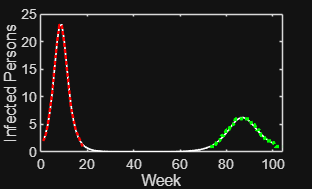

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
alpha = 1/60; % Resuseptible Rate
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = simulate_sirs(s_1, i_1, r_1, beta, gamma, alpha, week_end);

T_long = S_long + I_long + R_long;
assert(all(T_long-100 < 1e-10))

% Plot the fitted simulation
figure()
plot(W_long, I_long, 'w-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Wave 1')
plot(tab_data_wave2.Week, tab_data_wave2.InfectedCount, 'g:', 'LineWidth', 2.0, 'DisplayName', 'Wave 2')
xlabel("Week")
ylabel("Infected Persons")